# Assignment 10

# **Development of a tracking filter of a moving object when measurements and motion models are in different coordinate systems.**   

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

**1. Generate a true trajectory *****X***** of an object that moves uniformly. Trajectory is deterministic, as no random disturbance affect a motion.**

**2. Generate also true values of range **D** and azimuth **$\beta$**. Plot generated motion in polar coordinate system.**

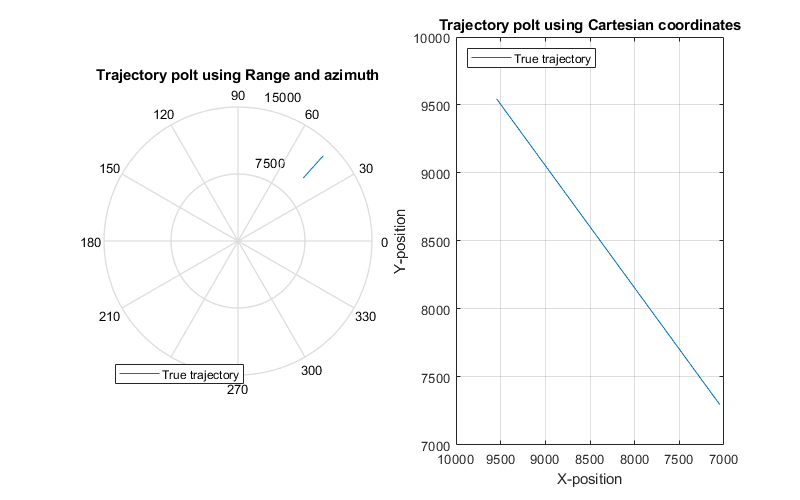

close all;
clear;

m = 1;    % Extrapolation steps
N = 26;   % Number of points
NE = N-m; % Number of points for the extrapolation error

X = zeros(1,N);           % X-position
Y = zeros(1,N);           % Y-position
X(1) = 13500/sqrt(2);     % X initial value
Y(1) = 13500/sqrt(2);     % Y initial value
Vx = -50;     % X velocity
Vy = -45;     % Y velocity
T = 2;        % Time step

D = zeros(1,N);             % Range
beta = zeros(1,N);          % Azimuth
D(1) = sqrt(X(1)^2+Y(1)^2); % Range initial value
beta(1) = atan2(X(1),Y(1));  % Azimuth initial value

sigma_d = 20;               % Range measurements noise standard deviation
sigma_beta = 0.02;          % Azimuth measurements noise standard deviation
% Vectors generation
for i = 2:N
    X(i) = X(i-1)+Vx*T;             % X vector generation
    Y(i) = Y(i-1)+Vy*T;             % Y vector generation
    D(i) = sqrt(X(i)^2+Y(i)^2);     % Range vector generation
    beta(i) = atan2(X(i),Y(i));      % Azimuth vector generation
end

% Trajectory plotting for visualization
figure
subplot(1,2,1)
polar(beta,D)
hold on
title('Trajectory polt using Range and azimuth')
legend({'True trajectory'},'location','southwest')

subplot(1,2,2)
plot(X,Y); set(gca, 'XDir','reverse')
title('Trajectory polt using Cartesian coordinates')
xlabel('X-position')
ylabel('Y-position')
legend({'True trajectory'},'location','northwest')
grid on
set(gcf,'position',[0,0,800,500]);

**Comment:**

In this plot we can see the similaritiy of the trajectory in both coordinates, and since the velocity is with a negative value we know that the trajectory is headed towards the observer in the polar coordinates which would correspond to zero in the cartesian coordinates. 

% Kalman errors initialization

Errx = zeros(500,N);          % X true estimation error
ErrxE = zeros(500,NE);        % X-extrapolated true estimation error
Erry = zeros(500,N);          % Y true estimation error
ErryE = zeros(500,NE);        % Y-extrapolated true estimation error
ErrD = zeros(500,N);          % D true estimation error
ErrDE = zeros(500,NE);        % D-extrapolated true estimation error
Errbeta = zeros(500,N);       % beta true estimation error
ErrbetaE = zeros(500,NE);     % beta-extrapolated true estimation error
K500 = zeros(500,N);           % kalman filter gain matrix

for M = 1:500
    
    X = zeros(1,N);           % X-position
    Y = zeros(1,N);           % Y-position
    X(1) = 13500/sqrt(2);     % X initial value
    Y(1) = 13500/sqrt(2);     % Y initial value
    Vx = -50;     % X velocity
    Vy = -45;     % Y velocity
    T = 2;        % Time step

    D = zeros(1,N);             % Range
    beta = zeros(1,N);          % Azimuth
    D(1) = sqrt(X(1)^2+Y(1)^2); % Range initial value
    beta(1) = atan2(X(1),Y(1));  % Azimuth initial value

**3. Generate measurements **$D^m$** and **$\beta^m$ **of range **D** and azimuth **$\beta$**.**

    sigma_d = 20;               % Range measurements noise standard deviation
    sigma_beta = 0.02;          % Azimuth measurements noise standard deviation
    
    normaldist = makedist('Normal',0,sigma_d);
    eta_d = random(normaldist,N,1);            % Range measurements noise vector

    normaldist = makedist('Normal',0,sigma_beta);
    eta_b = random(normaldist,N,1);            % Azimuth measurements noise vector
    D_m = D;                                   % Range measurements
    beta_m = beta;                             % Azimuth measurements

    D_m(1) = D(1)+eta_d(1);                    % Range measurements initialization
    beta_m(1) = beta(1)+eta_b(1);              % Azimuth measurements initialization
    
    % Vectors generation
    for i = 2:N
        X(i) = X(i-1)+Vx*T;             % X vector generation
        Y(i) = Y(i-1)+Vy*T;             % Y vector generation
        D(i) = sqrt(X(i)^2+Y(i)^2);     % Range vector generation
        beta(i) = atan2(X(i),Y(i));      % Azimuth vector generation

        D_m(i) = D(i)+eta_d(i);         % Range measurements vector generation
        beta_m(i) = beta(i)+eta_b(i);   % Azimuth measurements vector generation
    end

**4. Transform polar coordinates **$D^m$** and **$\beta^m$** to Cartesian ones and get pseudo-measurements of coordinates** $x$** and **$y$**.**

    X_m = D_m.*sin(beta_m);       % X measurements vector generation    
    Y_m = D_m.*cos(beta_m);       % Y measurements vector generation

**5. Create the measurement vector **$z$ **from pseudo-measurements of coordinates **$x$** and **$y$**.**

    Z = [X_m;Y_m];                % Cartesian measurments

    % Kalman filter parameters initialization
    xi = zeros(1,N);
    yi = zeros(1,N);

**6. Initial conditions for Kalman filter algorithm.**

    Xi = [40000;-20;40000;-20];   % State vector
    P = (10^10)*eye(4);           % P matrix

**7. Create the transition matrix **$\Phi$ **and observation matrix **$H$.

    % state space matrices
    phi = [1 T 0 0;0 1 0 0;0 0 1 T;0 0 0 1];
    H = [1 0 0 0;0 0 1 0];

**8. Create the measurement error covariance matrix R needed for Kalman filter algorithm.**

    % Initial measurement error covariance matrix
    R = [(sin(beta_m(1))*sigma_d)^2+(D_m(1)*cos(beta_m(1))*sigma_beta)^2 ...
        sin(beta_m(1))*cos(beta_m(1))*(sigma_d^2-(D_m(1)*sigma_beta)^2); ...
        sin(beta_m(1))*cos(beta_m(1))*(sigma_d^2-(D_m(1)*sigma_beta)^2) ...
        (cos(beta_m(1))*sigma_d)^2+(D_m(1)*sin(beta_m(1))*sigma_beta)^2];

**9. Develop Kalman filter algorithm to estimate state vector **$X_i$ **(extrapolation and filtration) At every extrapolation and filtration step you will need to calculate range D and Azimuth **$\beta$** from extrapolated and filtered estimates.**

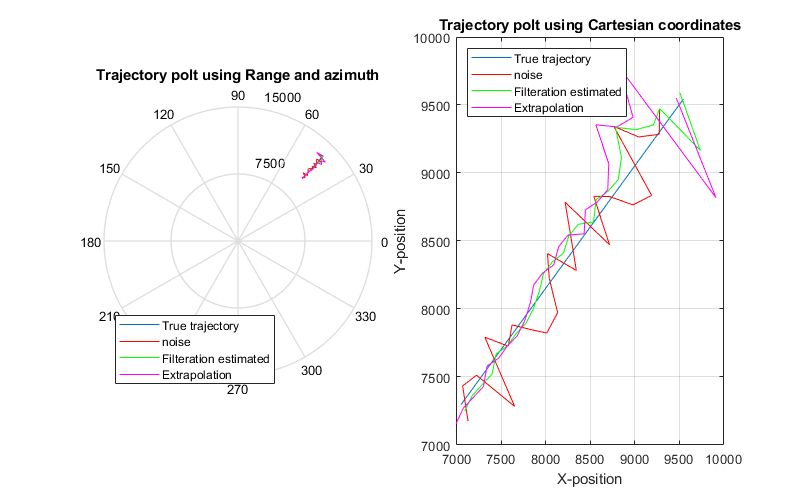

    K = P*H'/(H*P*H'+R);   % Kalman gain initialization

    Px = zeros(N,1);       % X Calculation error initialization
    Py = zeros(N,1);       % Y Calculation error initialization
    xiE = zeros(N,1);      % Extrapolated X
    yiE = zeros(N,1);      % Extrapolated Y

    Di = zeros(N,1);       % filtered Range
    betai = zeros(N,1);    % filtered Azimuth

    DiE = zeros(N,1);     % Extrapolated Range
    betaiE = zeros(N,1);  % Extrapolated Azimuth
    
    Ki = zeros(1,N);      % array of K(1,1)
    CN = zeros(1,N);      % condition number

    % Kalman filter
    for i = 1:N
        
        Ki(i) = K(1,1);
        R = [(sin(beta_m(i))*sigma_d)^2+(D_m(i)*cos(beta_m(i))*sigma_beta)^2 ...
            sin(beta_m(i))*cos(beta_m(i))*(sigma_d^2-(D_m(i)*sigma_beta)^2); ...
            sin(beta_m(i))*cos(beta_m(i))*(sigma_d^2-(D_m(i)*sigma_beta)^2) ...
            (cos(beta_m(i))*sigma_d)^2+(D_m(i)*sin(beta_m(i))*sigma_beta)^2];
        CN(i) = cond(R);

        Xi = phi*Xi;
        P = phi*P*phi';
        Xi = Xi+K*(Z(:,i)-H*Xi);
        xi(i) = Xi(1);
        yi(i) = Xi(3);

        K = P*H'/(H*P*H'+R);
        P = (eye(4)-K*H)*P;
        XiE = Xi;
        
        for mm = m
            XiE = phi*XiE;     % Extrapolated state vector
        end
        
        % Extrapolated X,Y
        xiE(i) = XiE(1);
        yiE(i) = XiE(3);
        
        % Range and azimuth estimation (filtered and extrapolated)
        Di(i) = sqrt(Xi(1)^2+Xi(3)^2);
        betai(i) = atan2(Xi(1),Xi(3));
        DiE(i) = sqrt(XiE(1)^2+XiE(3)^2);
        betaiE(i) = atan2(XiE(1),XiE(3));
        
        % True estimation error calculation
        Errx(M,i) = (Xi(1)-X(i))^2;
        Erry(M,i) = (Xi(3)-Y(i))^2;
        ErrD(M,i) = (Di(i)-D(i))^2;
        Errbeta(M,i) = (betai(i)-beta(i))^2;
        
        % Covariance matrix error
        Px(i) = sqrt(P(1,1));
        Py(i) = sqrt(P(3,3));
        
        % Extrapolation error calculation
        if i<N
            ErrxE(M,i) = (XiE(1)-X(i+m))^2;
            ErryE(M,i) = (XiE(3)-Y(i+m))^2;
            ErrDE(M,i) = (DiE(i)-D(i+m))^2;
            ErrbetaE(M,i) = (betaiE(i)-beta(i+m))^2;
        end
    end
    K500(M,:) = Ki;
end

% Trajectory plotting for visualization
figure
subplot(1,2,1)
polar(beta,D)
hold on
polar(beta_m,D_m,'r')
polar(betai,Di,'g')
polar(betaiE,DiE,'m')
title('Trajectory polt using Range and azimuth')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','southwest')

subplot(1,2,2)
plot(X,Y)
hold on
plot(X_m,Y_m,'r')
plot(xi,yi,'g')
plot(xiE,yiE,'m')
title('Trajectory polt using Cartesian coordinates')
xlabel('X-position')
ylabel('Y-position')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','northwest')
grid on
set(gcf,'position',[0,0,800,500]);

**Comment:**

In this figure above we can see the true trajectory, the measurements, the filtered and the extrapolated states for the X,Y in cartesian coordinates, and range and azimuth in polar coordinates. Both the estimation and extrapolation are converging to the true trajectory the closer they approach the observer and we can predict that the error is decreasing.

**10. Run Kalman filter algorithm over M = 500 runs. Calculate true errors of estimation:**

**        a) Errors of extrapolation and filtration estimates of range D relative to **$\sigma_D$

**        b) Errors of extrapolation and filtration estimates of Azimuth **$\beta
$** relative to **$\sigma_\beta$.

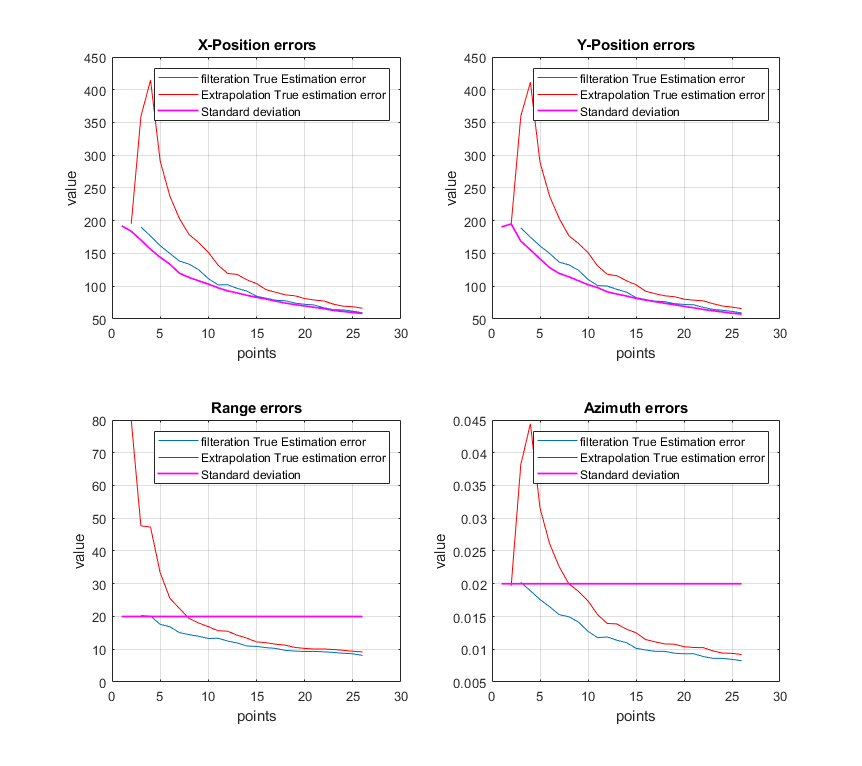

figure
% Error plotting
subplot(2,2,1)
plotErr(Errx,ErrxE,Px,'X-Position')
subplot(2,2,2)
plotErr(Erry,ErryE,Py,'Y-Position')
subplot(2,2,3)
plotErr(ErrD,ErrDE,sigma_d*ones(1,N),'Range')
subplot(2,2,4)
plotErr(Errbeta,ErrbetaE,sigma_beta*ones(1,N),'Azimuth')

% suptitle('True Estimation Error vs. Extrapolation error vs. standard deviation')

**Comment:**

The figures above represent the errors in coordinates X,Y and in Range D and azimuth. we can see that all errors are decreasing and converging to a value. for the coordinates X,Y the true estimation error and the calculation error from Kalman are having the same trend and almost the same values. and similarly for the extrapolation at the end of the measurements as it settles for a value close to them but a bit higher. For the range and azimuth, the Azimuth error is having the same tredn of the coordinates error and is close to $\sigma_\beta$ and settling for and error value almost 0.1 which is less than the error standard deviation which indicates a good estimation accuracy, and the same for the range except that the extrapolation error has different trend than the coordinates and is starting high then settling with no peak.

**11. Analyze dependence of coordinate X on azimuth **$\textbf{\beta}$.

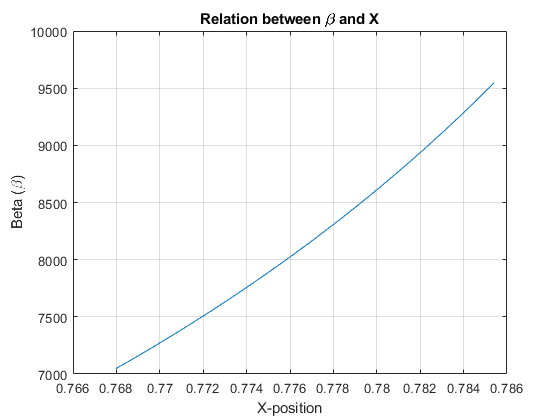

figure
plot(beta,X)
title('Relation between \beta and X')
grid on
xlabel('X-position')
ylabel('Beta (\beta)')

**Comment:**

Plotting the X versus the azimuth which should be a nonlinear relation according to its equation, but we can visually say that the relation is almost linear withim our range, which mean that this dependence's linearization errors are insignificant and we can rely on our results.

**12. Calculate condition number of covariance matrix R over the observation interval.**

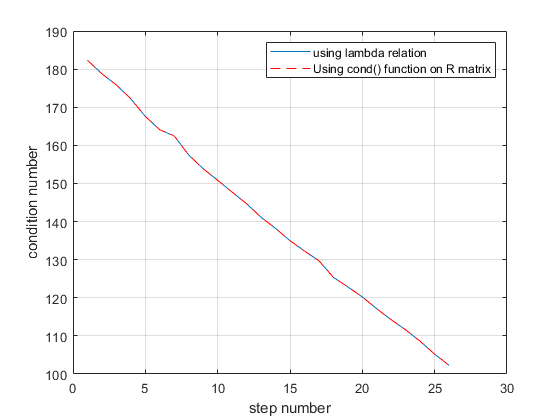

% condition number
ConditionNo = ((D_m.^2).*sigma_beta^2)./sigma_d^2;
if min(ConditionNo)<1
    for j = 1:N
        if ConditionNo(j)<1
            ConditionNo(j) = 1./ConditionNo(j);
        end
    end
end

figure
plot(ConditionNo)
grid on
hold on
plot(CN,'--r')
legend('using lambda relation','Using cond() function on R matrix')
xlabel('step number')
ylabel('condition number')
grid on

**Comment:**

Plotting the condition number over the observation interval we can see that the number is decreasing over time which means that the estimation accuracy is increasing and indicates that our filter estimates would converge eventually; Also we can see, that it's relativly modereate not too big (Conditoin number = 1000) or too perfect (Condition number = 1), which means that our matrix is well conditioned and we don't have to use the full formulation for error covariance matrix and that our estimation is consistent.

We used too formulations to make verify that our calculations are accurate, we calculated the Condition number directly from the R matrix using MATLAB's cond() function, and the formulation from the slides using the eigen values; and the end result was the same that you can see from the graph that they both are identical and plotted above each other.

**13. An****alyze filter gain  K.**

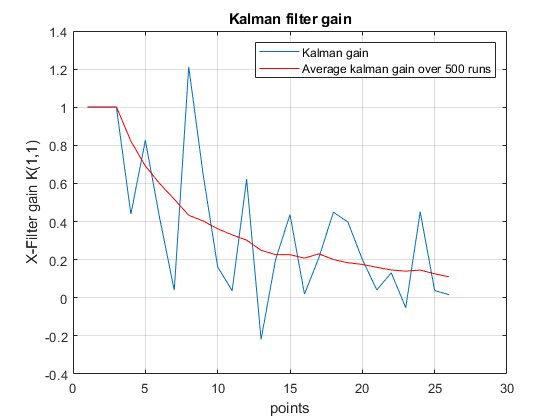

Ki2 = zeros(1,N);  % Average Kalman gain over 500 runs
for j = 1:N;
    Ki2(j) = (1/(M-1))*sum(K500(:,j));
end
figure
plot(Ki)
hold on
plot(Ki2,'r')
grid on
title('Kalman filter gain')
xlabel('points')
ylabel('X-Filter gain K(1,1)')
legend('Kalman gain' , 'Average kalman gain over 500 runs')

**Comment:**

Ananlyzing the filter gain from the individual run, We can see that the filter gain is not settling and disturbed and have unusal behaviour that it's sometimes exceeding 1 in top and 0 in bottom, and that can be accounted for the R matrix's condition number that it's between 200 and 100, that the gain can't settle for a value but oscillates around almost 0.2. However, the disturbances are decreasing as we approach the observer and that's because the condition number is decreasing too. That behaviour can be seen clearly at the averaged filter gain with the decrease and the settling of the value around 0.2.

**14. Run filter again over **$M=500$** runs but use other initial conditions to generate a trajectory **


$$x_0 =\frac{3500}{\sqrt{\;2}}\;,y_0 =\frac{3500}{\sqrt{\;2}}$$


clear;
N = 26;
m = 1;
M = 500;
x1 = 3500/sqrt(2);
y1 = 3500/sqrt(2);
sigma_d = 20;
sigma_beta = 0.02;
[ Errx,ErrxE,Erry,ErryE,ErrD,ErrDE,Errbeta,ErrbetaE,Px,Py,...
    X,Y,xi,yi,xiE,yiE,X_m,Y_m ...
    ,D,beta,D_m,beta_m,Di,betai,DiE,betaiE,Ki,K500,CN]  =  KalmaPolarMeasurements( x1,y1,N,m,M,sigma_beta,sigma_d );

**14.1 ploting the trajectory for visualization. **

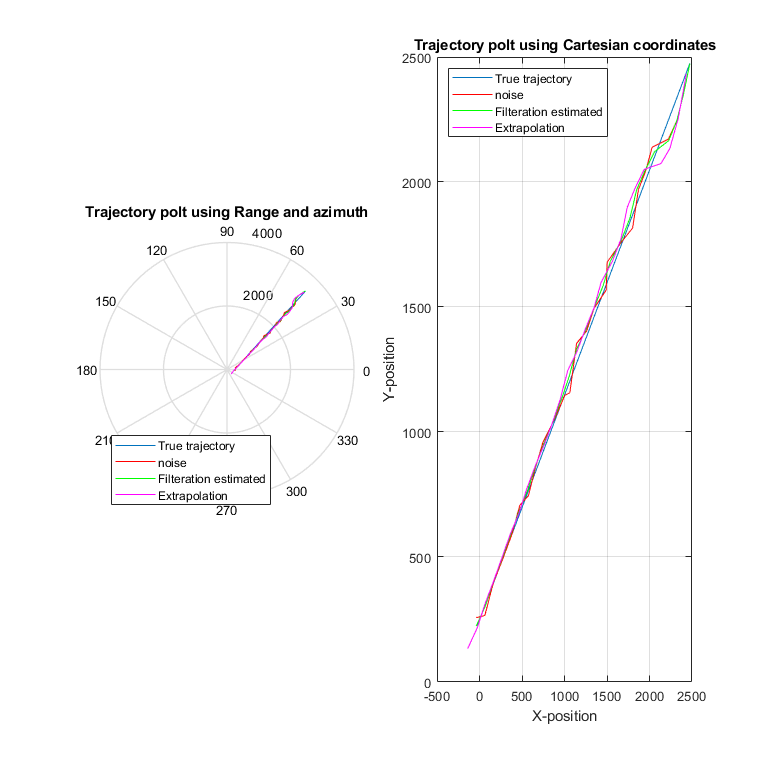

% Trajectory plotting for visualization
figure
subplot(1,2,1)

polar(beta,D)
hold on
polar(beta_m,D_m,'r')
polar(betai,Di,'g')
polar(betaiE,DiE,'m')
title('Trajectory polt using Range and azimuth')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','southwest')

subplot(1,2,2)
plot(X,Y)
hold on
plot(X_m,Y_m,'r')
plot(xi,yi,'g')
plot(xiE,yiE,'m')
title('Trajectory polt using Cartesian coordinates')
xlabel('X-position')
ylabel('Y-position')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','northwest')
grid on
set(gcf,'position',[0,0,800,800]);

**Comment:**

**15. Calculate true errors of estimation**

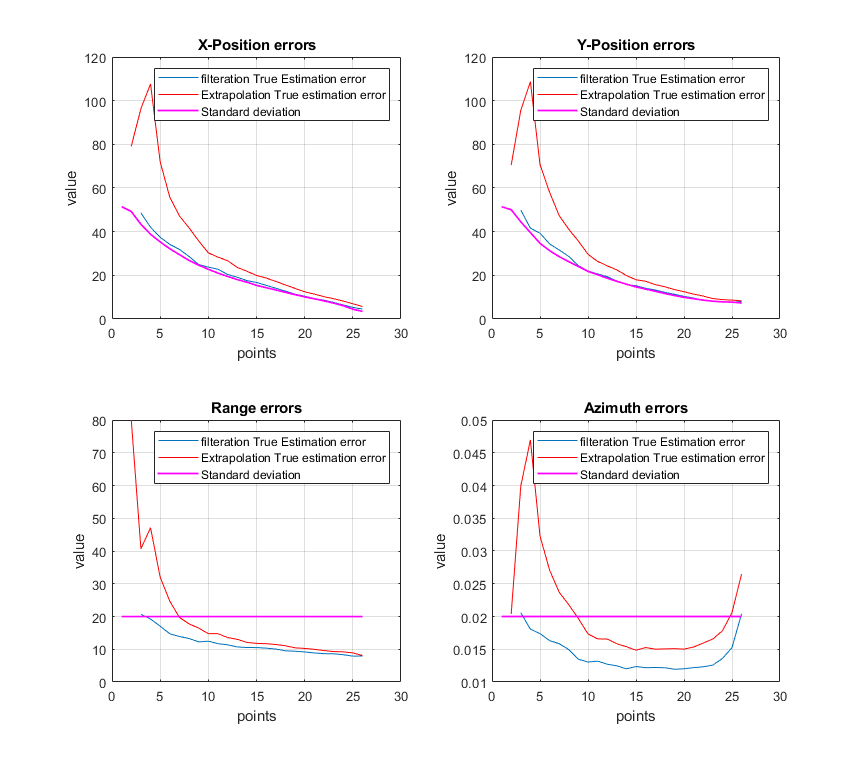

figure
% Error plotting
subplot(2,2,1)
plotErr(Errx,ErrxE,Px,'X-Position')
subplot(2,2,2)
plotErr(Erry,ErryE,Py,'Y-Position')
subplot(2,2,3)
plotErr(ErrD,ErrDE,sigma_d*ones(1,N),'Range')
subplot(2,2,4)
plotErr(Errbeta,ErrbetaE,sigma_beta*ones(1,N),'Azimuth')

% suptitle('True Estimation Error vs. Extrapolation error vs. standard deviation')

**Comment:**

**16. Analyze dependence of coordinate **$x$**on azimuth **$\beta$.

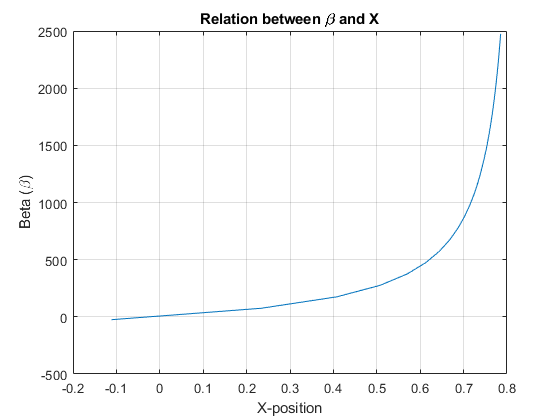

figure
plot(beta,X)
title('Relation between \beta and X')
grid on
xlabel('X-position')
ylabel('Beta (\beta)')

**Comment:**

**17. Calculate condition number of covariance matrix R over the observation interval for these conditions. Does condition number decrease or increase over time?**

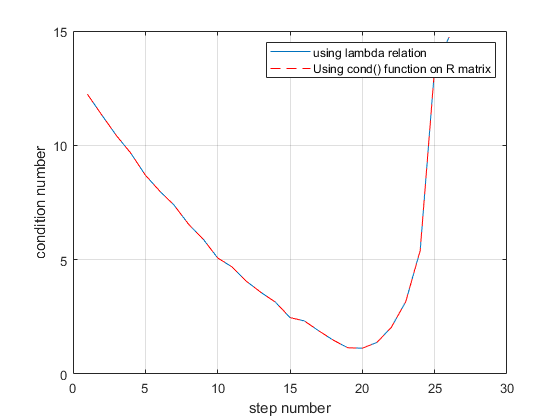

% condition number
ConditionNo = ((D_m.^2).*sigma_beta^2)./sigma_d^2;
if min(ConditionNo)<1
    for j = 1:N
        if ConditionNo(j)<1
            ConditionNo(j) = 1./ConditionNo(j);
        end
    end
end

figure
plot(ConditionNo)
grid on
hold on
plot(CN,'--r')
legend('using lambda relation','Using cond() function on R matrix')
xlabel('step number')
ylabel('condition number')
grid on

**Comment:**

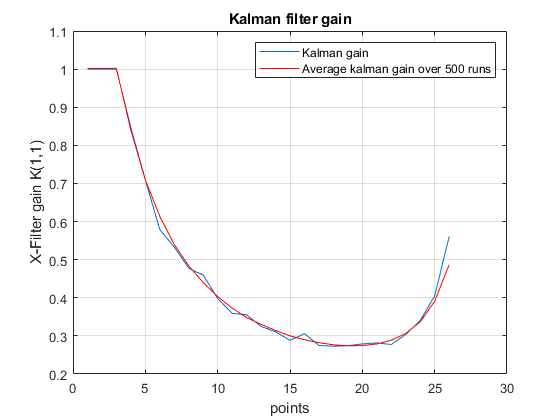

Ki2 = zeros(1,N);  % Average Kalman gain over 500 runs
for j = 1:N;
    Ki2(j) = (1/(M-1))*sum(K500(:,j));
end
figure
plot(Ki)
hold on
plot(Ki2,'r')
grid on
title('Kalman filter gain')
xlabel('points')
ylabel('X-Filter gain K(1,1)')
legend('Kalman gain' , 'Average kalman gain over 500 runs')

**Comment:**

**19. Run filter again over **$M=500$** runs but use other initial conditions to generate a trajectory (**$\sigma_D=50 , \sigma_\beta=0.0015$**)**


$$x_0 =\frac{3500}{\sqrt{\;2}}\;,y_0 =\frac{3500}{\sqrt{\;2}}$$


clear;
N = 26;
m = 1;
M = 500;
x1 = 3500/sqrt(2);
y1 = 3500/sqrt(2);
sigma_d = 50;
sigma_beta = 0.0015;
[ Errx,ErrxE,Erry,ErryE,ErrD,ErrDE,Errbeta,ErrbetaE,Px,Py,...
    X,Y,xi,yi,xiE,yiE,X_m,Y_m ...
    ,D,beta,D_m,beta_m,Di,betai,DiE,betaiE,Ki,K500,CN]  =  KalmaPolarMeasurements( x1,y1,N,m,M,sigma_beta,sigma_d );

**20. Repeat items 14,15,16,17 for these conditions and reply to questions addressed.**

**20.(14.1) ploting the trajectory for visualization. **

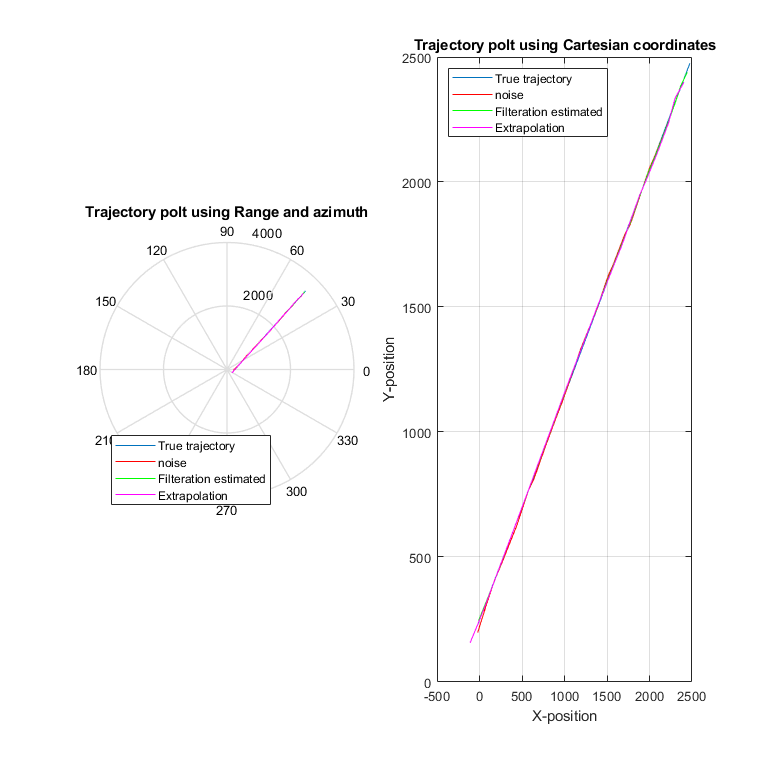

% Trajectory plotting for visualization
figure
subplot(1,2,1)

polar(beta,D)
hold on
polar(beta_m,D_m,'r')
polar(betai,Di,'g')
polar(betaiE,DiE,'m')
title('Trajectory polt using Range and azimuth')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','southwest')

subplot(1,2,2)
plot(X,Y)
hold on
plot(X_m,Y_m,'r')
plot(xi,yi,'g')
plot(xiE,yiE,'m')
title('Trajectory polt using Cartesian coordinates')
xlabel('X-position')
ylabel('Y-position')
legend({'True trajectory','noise','Filteration estimated','Extrapolation'},'location','northwest')
grid on
set(gcf,'position',[0,0,800,800]);

**Comment:**

**20.(15) Calculate true errors of estimation**

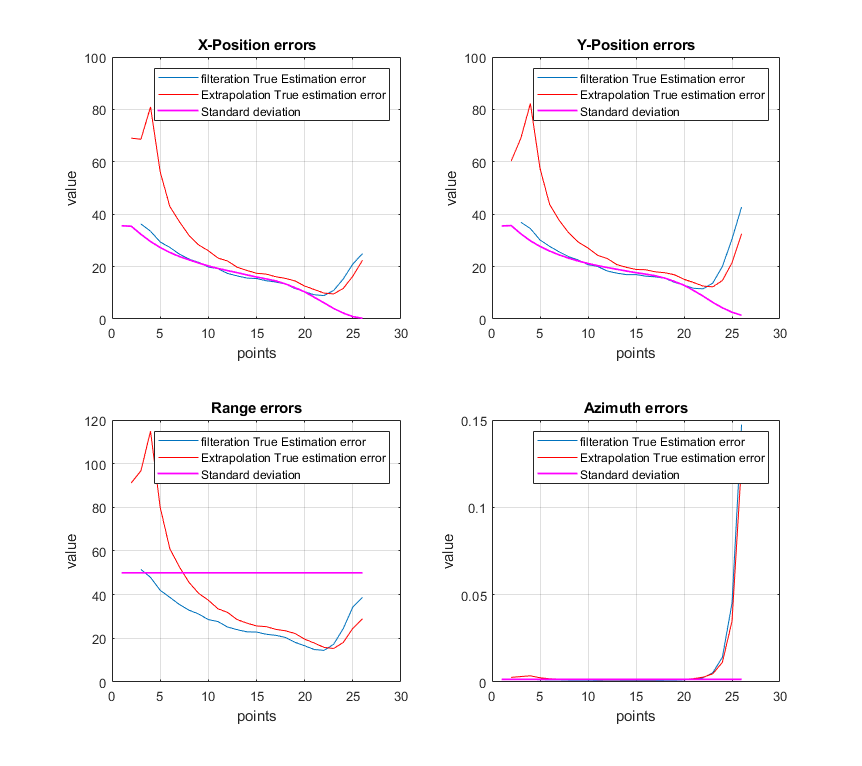

figure
% Error plotting
subplot(2,2,1)
plotErr(Errx,ErrxE,Px,'X-Position')
subplot(2,2,2)
plotErr(Erry,ErryE,Py,'Y-Position')
subplot(2,2,3)
plotErr(ErrD,ErrDE,sigma_d*ones(1,N),'Range')
subplot(2,2,4)
plotErr(Errbeta,ErrbetaE,sigma_beta*ones(1,N),'Azimuth')

% suptitle('True Estimation Error vs. Extrapolation error vs. standard deviation')

**Comment:**

**20.(16) Analyze dependence of coordinate **$x$**on azimuth **$\beta$.

figure
plot(beta,X)
title('Relation between \beta and X')
grid on
xlabel('X-position')
ylabel('Beta (\beta)')

**Comment:**

**20.(17) Calculate condition number of covariance matrix R over the observation interval for these conditions. Does condition number decrease or increase over time?**

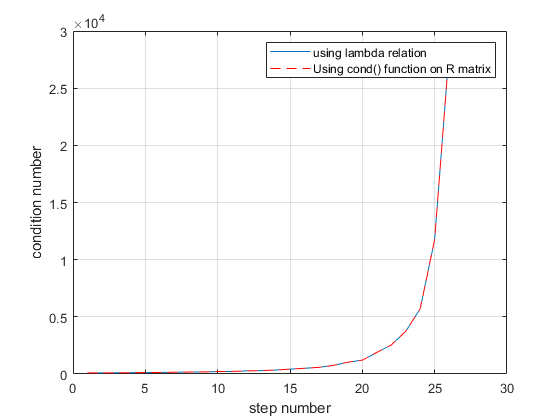

% condition number
ConditionNo = ((D_m.^2).*sigma_beta^2)./sigma_d^2;
if min(ConditionNo)<1
    for j = 1:N
        if ConditionNo(j)<1
            ConditionNo(j) = 1./ConditionNo(j);
        end
    end
end

figure
plot(ConditionNo)
grid on
hold on
plot(CN,'--r')
legend('using lambda relation','Using cond() function on R matrix')
xlabel('step number')
ylabel('condition number')
grid on

**Comment:**

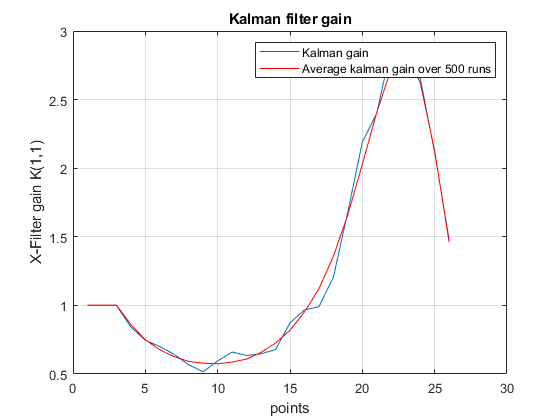

Ki2 = zeros(1,N);  % Average Kalman gain over 500 runs
for j = 1:N;
    Ki2(j) = (1/(M-1))*sum(K500(:,j));
end
figure
plot(Ki)
hold on
plot(Ki2,'r')
grid on
title('Kalman filter gain')
xlabel('points')
ylabel('X-Filter gain K(1,1)')
legend('Kalman gain' , 'Average kalman gain over 500 runs')

**Comment:**

**General conclusion:**

# **Learning log:**